%Load in some references and set dummy inputs
wgs84 = wgs84Ellipsoid('meter'); load coastlines;
myPosition = [42.26445, -76.28958, 244.7] %[in Ithaca], Lat Long H

myPosition =    42.2644  -76.2896  244.7000


issPosition_static = [-42.9277, -121.3160, 421.0*1000.0];
apiRequest = webread("http://api.open-notify.org/iss-now.json").iss_position;
issPosition = [str2num(apiRequest.latitude), str2num(apiRequest.longitude), 421E3]

issPosition = 	1.0e+05 *

   -0.0003   -0.0009    4.2100



[myX, myY, myZ] = geodetic2ecef(wgs84,myPosition(1),myPosition(2),myPosition(3));
[issX,issY,issZ] = geodetic2ecef(wgs84,issPosition(1),issPosition(2),issPosition(3));
[coastX, coastY, coastZ] = geodetic2ecef(wgs84,coastlat,coastlon,zeros(size(coastlon)));

%Converts a lat/lon/h location to East/North/Up cartesian coordinates
%[xEast,yNorth,zUp] = geodetic2enu(lat,lon,h,lat0,lon0,h0,spheroid)
[xEast,yNorth,zUp] = ...
    geodetic2enu(issPosition(1),issPosition(2),issPosition(3), ...
    myPosition(1),myPosition(2),myPosition(3),wgs84)

xEast = -1.4613e+06

yNorth = -6.4603e+06

zUp = -4.9587e+06

pointingVector = [xEast,yNorth,zUp]/norm([xEast,yNorth,zUp])

pointingVector =    -0.1766   -0.7808   -0.5993



%Computes the pair of angle solutions which will point at that point
rotationSolution_1 = atan2d(pointingVector(2),pointingVector(1))

rotationSolution_1 = -102.7458

elevationSolution_1 = acosd(pointingVector(3))

elevationSolution_1 = 126.8205

rotationSolution_2 = mod((rotationSolution_1+180),360)

rotationSolution_2 = 77.2542

elevationSolution_2 = 360 - elevationSolution_1

elevationSolution_2 = 233.1795

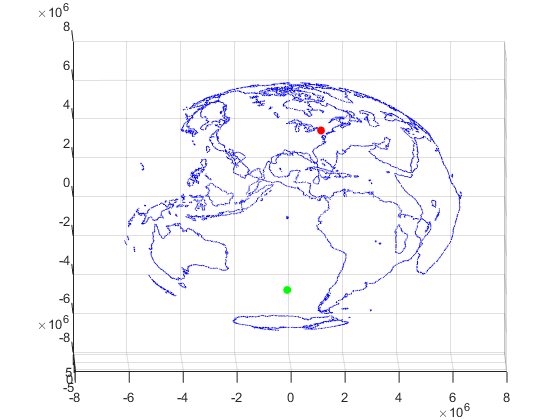


figure();
scatter3(coastX, coastY, coastZ,1,'blue','filled'); hold on;
scatter3(myX, myY, myZ,'r','filled')
scatter3(issX, issY, issZ,'g','filled')